# Create a simple Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

## Create Array of Layers

layers = [
    featureInputLayer(6,"Name","featureinput")
    reluLayer("Name","relu1")
    fullyConnectedLayer(128,"Name","fc1")
    reluLayer("Name","relu2")
    fullyConnectedLayer(64,"Name","fc2")
    fullyConnectedLayer(1,"Name","fc3")
    sigmoidLayer("Name", "Classifier")
    regressionLayer("Name","output")
    ];

## Plot Layers

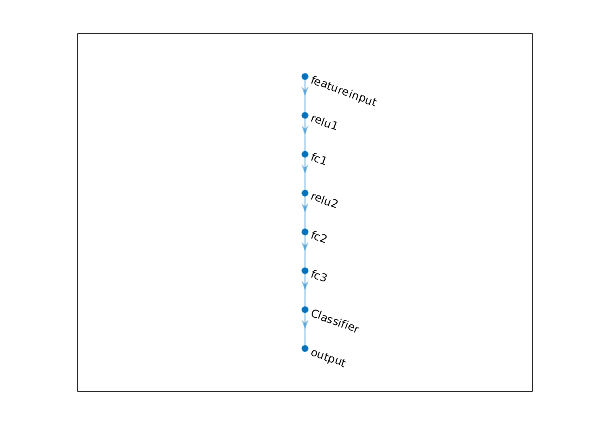

plot(layerGraph(layers));

## **Choose optimizer and hyper-parameters**

We will use Stochastic Gradient Descent optimizer with a fix learning:


$$\alpha =1e^{-2}$$



$$\textrm{epochs}=20$$



$$\textrm{batch}=64$$


options = trainingOptions("sgdm", ...
    MaxEpochs=100, ...
    InitialLearnRate=0.01, ...
    Plots="training-progress", ...
    MiniBatchSize=364, ...
    Verbose=1)

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 100
                   MiniBatchSize: 364
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'training-progress'
                  SequenceLeng

## **Ok, now it's training time!**

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |         0.53 |          0.1 |          0.0100 |
|       1 |          50 |       00:00:08 |         0.48 |          0.1 |          0.0100 |
|       1 |         100 |       00:00:09 |         0.47 |          0.1 |          0.0100 |
|       1 |         150 |       00:00:09 |         0.45 |          0.1 |          0.0100 |
|       2 |         200 |       00:00:10 |         0.44 |      9.7e-02 |          0.0100 |
|       2 |         250 |       00:00:11 |         0.43 |      9.4e-02 |          0.0100 |
|       2 |         300 |       00:00:11 |         0.42 |      8.8

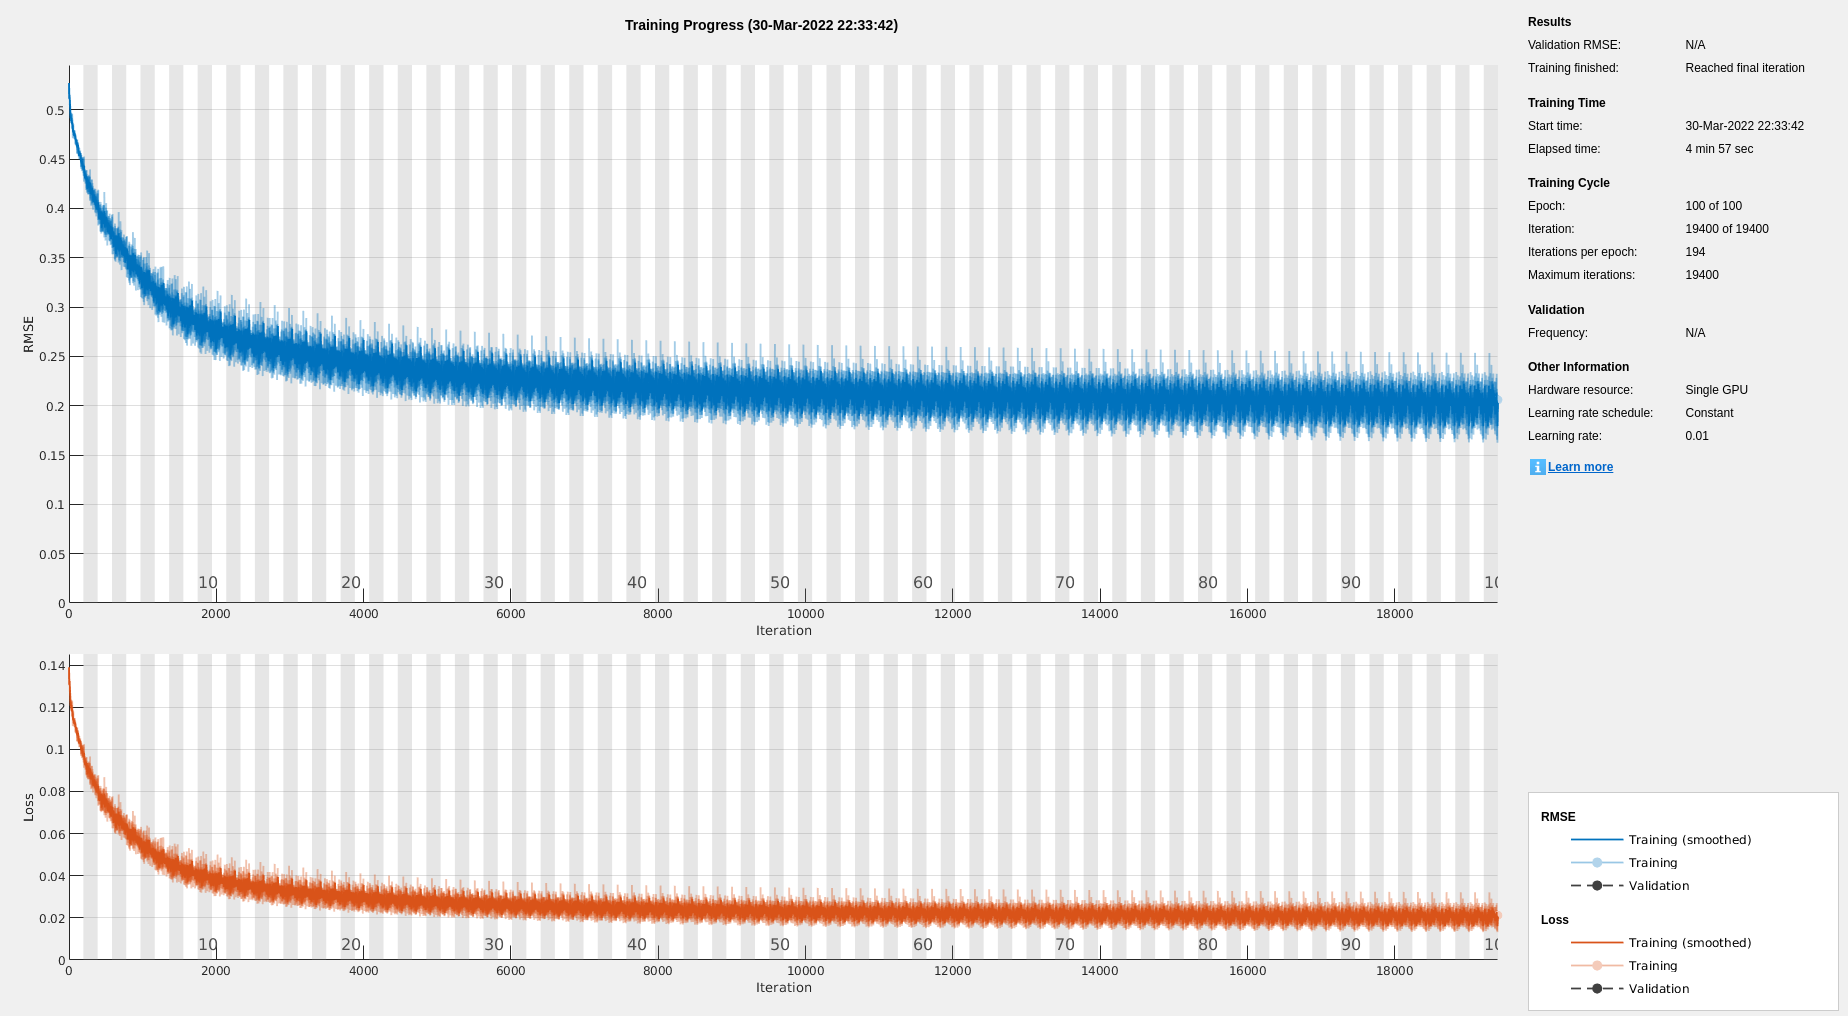

net = trainNetwork(Xtrain,Ytrain,layers,options);

## **Test time!**

Y = predict(net,Xtest);
for i=1:size(Y,1)
if Y(i,1) > 0.5
    Y(i,1) = 1;
else
    Y(i,1) = 0;
end
end

c = confusionmat(Ytest, double(Y));
c = (c/size(Y,1).*100);
c = round(c)

c =     48     2
     3    47


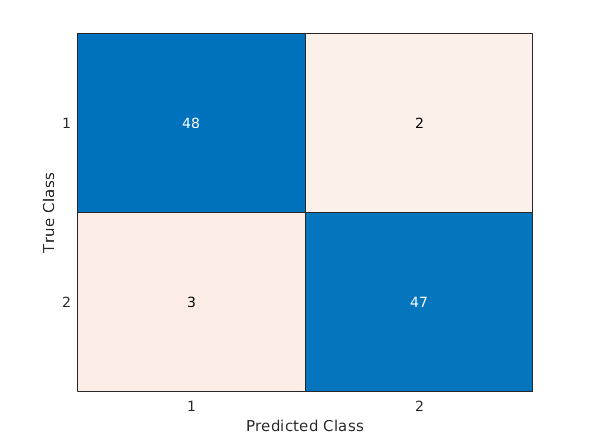

confusionchart(c)

acc = (c(1,1)+c(2,2))

acc = 95

disp('Clssficiation accuracy is in percent: ')

Clssficiation accuracy is in percent: 


disp(acc)

    95

